clc,clear
% n=8;
% A=randn(n)
% b=randn(n,1);
A=[10,-1,-2;-1,10,-2;-1,-1,5];
b=[7.2;8.3;4.2];
iter_max=100;
tol=1e-10;

## Jacobi method

toc

历时 29.463890 秒。


[x,~,~,error_his1]=Jacobi(A,b,iter_max,tol);

iter_num= 1 Error=3.80e+00
iter_num= 2 Error=1.32e+00
iter_num= 3 Error=4.36e-01
iter_num= 4 Error=1.49e-01
iter_num= 5 Error=4.98e-02
iter_num= 6 Error=1.69e-02
iter_num= 7 Error=5.67e-03
iter_num= 8 Error=1.92e-03
iter_num= 9 Error=6.46e-04
iter_num= 10 Error=2.18e-04
iter_num= 11 Error=7.35e-05
iter_num= 12 Error=2.48e-05
iter_num= 13 Error=8.36e-06
iter_num= 14 Error=2.82e-06
iter_num= 15 Error=9.51e-07
iter_num= 16 Error=3.21e-07
iter_num= 17 Error=1.08e-07
iter_num= 18 Error=3.65e-08
iter_num= 19 Error=1.23e-08
iter_num= 20 Error=4.15e-09
iter_num= 21 Error=1.40e-09
iter_num= 22 Error=4.72e-10
iter_num= 23 Error=1.59e-10
iter_num= 24 Error=5.36e-11
误差小于:1.00e-10
退出循环

tic 
disp(['最终解为：',num2str(x')])

最终解为：1.1         1.2         1.3


## SOR method

toc

历时 0.009492 秒。


[x,~,~,error_his2]=SOR(A,b,iter_max,tol,[],1.05);

iter_num= 1 Error=3.69e+00
iter_num= 2 Error=2.09e-01
iter_num= 3 Error=5.29e-03
iter_num= 4 Error=4.78e-04
iter_num= 5 Error=5.27e-05
iter_num= 6 Error=3.99e-06
iter_num= 7 Error=3.49e-07
iter_num= 8 Error=3.10e-08
iter_num= 9 Error=2.66e-09
iter_num= 10 Error=2.31e-10
iter_num= 11 Error=2.01e-11
误差小于:1.00e-10
退出循环

tic
disp(['最终解为：',num2str(x')])

最终解为：1.1         1.2         1.3


## Gauss——Seidel

toc

历时 0.004554 秒。


[x,~,~,error_his3]=SOR(A,b,iter_max,tol,[],1);

w=1 <=> Gauss-Seidel method
iter_num= 1 Error=3.98e+00
iter_num= 2 Error=5.53e-01
iter_num= 3 Error=6.77e-02
iter_num= 4 Error=8.58e-03
iter_num= 5 Error=1.08e-03
iter_num= 6 Error=1.36e-04
iter_num= 7 Error=1.70e-05
iter_num= 8 Error=2.14e-06
iter_num= 9 Error=2.70e-07
iter_num= 10 Error=3.39e-08
iter_num= 11 Error=4.27e-09
iter_num= 12 Error=5.37e-10
iter_num= 13 Error=6.76e-11
误差小于:1.00e-10
退出循环

tic
disp(['最终解为：',num2str(x')])

最终解为：1.1         1.2         1.3


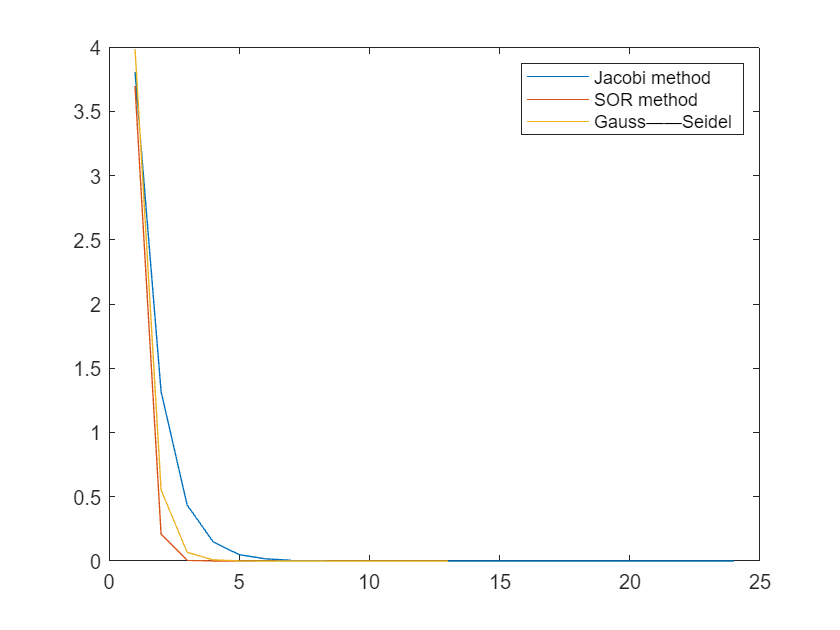

plot(1:length(error_his1),error_his1,1:length(error_his2),error_his2,1:length(error_his3),error_his3)
legend('Jacobi method','SOR method','Gauss——Seidel')
hold off

## 迭代速度：SOR（w=1.05）>Gauss Seidel > Jacobi

function [x,Error,x_his,error_his]=Jacobi(A,b,iter_max,tol,x0)
% Jacobi 迭代方法求解线性方程组 Ax=b。
% 输入参数：
%   A: 系数矩阵
%   b: 右侧常数向量
%   iter_max: 最大迭代次数（可选，默认为100）
%   tol: 收敛容差（可选，默认为1e-8）
%   x0: 初始解向量（可选，默认为全零向量）
% 输出参数：
%   x: 求解得到的解向量
%   Error: 每次迭代的误差
%   x_his: 每次迭代得到的解向量历史记录
%   error_his: 每次迭代的误差历史记录
[~,n]=size(A);
D=zeros(n);
if isempty(iter_max)
    iter_max=100;
end
if isempty(tol)
    tol=1e-8;
end
if nargin==5
    x=x0;
else
    x=zeros(n,1);
end
x_his=x'.*ones(iter_max,n); %以行的形式存储解
error_his=zeros(iter_max,1);
iter_num=1;
for i=1:n
     D(i,i)=A(i,i);
end
while iter_num<iter_max
    temp=x;
    for k=1:n        
        x(k)=(-A(k,:)*temp+A(k,k)*temp(k)+b(k))/A(k,k);
    end
    x_his(iter_num,:)=x;
    Error=norm(A*x-b);
    fprintf('iter_num= %d Error=%.2e\n',iter_num,Error)
    error_his(iter_num)=Error;
    if Error<=tol
        fprintf('误差小于:%.2e\n退出循环',tol)
        error_his=error_his(1:iter_num);
        x_his=x_his(1:iter_num,:);
        break;        
    end
    iter_num=iter_num+1;    
end
if iter_num==iter_max
    fprintf('达到最大迭代次数，误差为：%.2e',error_his(end))
end
end



function [x,Error,x_his,error_his]=SOR(A,b,iter_max,tol,x0,w)
% SOR (Successive Over-Relaxation) 方法求解线性方程组 Ax=b。
% 输入参数：
%   A: 系数矩阵
%   b: 右侧常数向量
%   w: 松弛因子（可选，默认为1.3）
%   iter_max: 最大迭代次数（可选，默认为100）
%   tol: 收敛容差（可选，默认为1e-8）
%   x0: 初始解向量（可选，默认为全零向量）
% 输出参数：
%   x: 求解得到的解向量
%   Error: 每次迭代的误差
%   x_his: 每次迭代得到的解向量历史记录
%   error_his: 每次迭代的误差历史记录
%   w=1 为Gauss-Seidel
    
    [~,n]=size(A); 
    error_his=zeros(iter_max,1);
    iter_num=1;
    if nargin<3
        iter_max=100;
    end
    if nargin<4
        tol=1e-8;
    end
    if nargin<5
        x0=zeros(n,1);
        x=x0;
    end
    if nargin<6
        w=1.3;
         fprintf('松弛因子w=1.3\n')
    elseif nargin==6
        if w==1
            fprintf('w=1 <=> Gauss-Seidel method\n')
        end
    end
    if isempty(x0)
        x=zeros(n,1);
    end
    x_his=x'.*ones(iter_max,n); %以行的形式存储
    x_pre=x;
    x_hat=x;
    while iter_num<iter_max        
        for k=1:n        
            x_hat(k)=(-A(k,:)*x+A(k,k)*x(k)+b(k))/A(k,k);
            x(k)=(1-w)*x_pre(k)+w*x_hat(k);
        end
        x_his(iter_num,:)=x';
        Error=norm(A*x-b);
        fprintf('iter_num= %d Error=%.2e\n',iter_num,Error)
        error_his(iter_num)=Error;
        if Error<=tol
            fprintf('误差小于:%.2e\n退出循环',tol)
            error_his=error_his(1:iter_num);
            x_his=x_his(1:iter_num,:);
            break;        
        end
        x_pre=x;
        iter_num=iter_num+1;    
    end
    if iter_num==iter_max
        fprintf('达到最大迭代次数，误差为：%.2e',error_his(end))
    end
end